## 11/01/2016

### Exercise 1,2

Three link robot, with link length L = 0.5

qnum = 3; %Number of joints
q = sym('q', [1 qnum]);
d = sym('d', [1 qnum]);
a = sym('a', [1 qnum]); 

L = sym('L')

$$L = L$$

armLength = 0.5

armLength = 0.5000

dhThreeLink = [L 0 0 q(1);
               L 0 0 q(2);
               L 0 0 q(3)]

$$dhThreeLink = \left(\begin{array}{cccc} L & 0 & 0 & q_{1}\\ L & 0 & 0 & q_{2}\\ L & 0 & 0 & q_{3} \end{array}\right)$$


T0_EE = getTranslationMatrix(dhThreeLink)

$$T0\_EE = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & 0 & L\,\left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & 0 & L\,\left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R = 'R';
P = 'P';
config = [R,R,R];

[Jp, Jo] = getJacobian(dhThreeLink,config);

Jac = [Jp;Jo];
%Eliminate the zero rows, which represent the unused variables
Jac(~all(Jac == 0,2),:);

Considering the case where $q=\left\lbrack 30°,30°,120°\right\rbrack$

qt = (pi/180)*[30,30,120] %q target in radians

qt =     0.5236    0.5236    2.0944



%For this particular case, it is possible to set the position vector and
%velocity like this

r = [T0_EE(1,4) ;
     T0_EE(2,4) ;
     q(1)+q(2)+q(3)]

$$r = \left(\begin{array}{c} L\,\left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ L\,\left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ q_{1}+q_{2}+q_{3} \end{array}\right)$$


%compute the jacobian for the 
J = jacobian(r,q) %It's equivalent than getting it by the direct method

$$J = \begin{array}{l} \left(\begin{array}{ccc} -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -L\,\sigma_{1}\\ L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & L\,\sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


%evaluate J in the given points
Jqt = subs(J,q,qt)

$$Jqt = \left(\begin{array}{ccc} -L\,\left(\frac{\sqrt{3}}{2}+\frac{1}{2}\right) & -\frac{\sqrt{3}\,L}{2} & 0\\ L\,\left(\frac{\sqrt{3}}{2}-\frac{1}{2}\right) & -\frac{L}{2} & -L\\ 1 & 1 & 1 \end{array}\right)$$

rank(Jqt)

ans = 3

det(Jqt)

$$ans = \frac{L^{2}}{2}$$

Jqt = subs(Jqt,L,0.5)

$$Jqt = \left(\begin{array}{ccc} -\frac{\sqrt{3}}{4}-\frac{1}{4} & -\frac{\sqrt{3}}{4} & 0\\ \frac{\sqrt{3}}{4}-\frac{1}{4} & -\frac{1}{4} & -\frac{1}{2}\\ 1 & 1 & 1 \end{array}\right)$$

For such case, the rank is full. So, there are no singularities. 

Subsequently, the evaluation of q' parameters is computed on $v_x =0,v_y =1,\omega_z =0$.

rdot = [0, 1, 0].'

rdot =      0
     1
     0


qdot = inv(Jqt)*rdot

$$qdot = \left(\begin{array}{c} 2\,\sqrt{3}\\ -2\,\sqrt{3}-2\\ 2 \end{array}\right)$$

%There are not multiple solutions for the problem.

$\dot{q} =J^{-1} *\dot{r} =\left(\begin{array}{c}
2\,\sqrt{3}\\
-2\,\sqrt{3}-2\\
2
\end{array}\right)\;\frac{\mathrm{rad}}{s}$.

The answer represents the rate of change of angle that the joints must have in order to move at that speed.

Fe = [-5,0,0].' %Force applied to the robot. Has tto be balanced.

Fe =     -5
     0
     0


T = -Jqt*Fe %It's negative, since it has to be contrary to the applied external force.

$$T = \left(\begin{array}{c} -\frac{5\,\sqrt{3}}{4}-\frac{5}{4}\\ \frac{5\,\sqrt{3}}{4}-\frac{5}{4}\\ 5 \end{array}\right)$$

eval(T)

ans =    -3.4151
    0.9151
    5.0000


%The units of the result is Nm. It is a single solution.

### Exercise 3

T = 100 % Not given. Only as example

T = 100

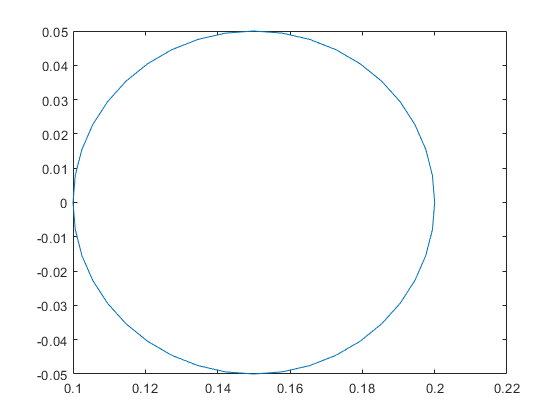

t = 0:0.01:T;

x = 0.15+0.05*cos(5*pi*t);
y = 0.05*sin(5*pi*t);
plot(x,y)

syms t T
pd = [0.15 + 0.05*cos(5*pi*t);
      0.05*sin(5*pi*t)] %Position of end-effector

$$pd = \left(\begin{array}{c} \frac{\cos\left(5\,\pi \,t\right)}{20}+\frac{3}{20}\\ \frac{\sin\left(5\,\pi \,t\right)}{20} \end{array}\right)$$

vt = diff(pd) %Velocity of end effector

$$vt = \left(\begin{array}{c} -\frac{\pi \,\sin\left(5\,\pi \,t\right)}{4}\\ \frac{\pi \,\cos\left(5\,\pi \,t\right)}{4} \end{array}\right)$$

t1 = 0.2

t1 = 0.2000

pd1 = subs(pd,t,t1)

$$pd1 = \left(\begin{array}{c} \frac{1}{10}\\ 0 \end{array}\right)$$

vt1 = subs(vt,t,t1)

$$vt1 = \left(\begin{array}{c} 0\\ -\frac{\pi }{4} \end{array}\right)$$

syms l1 l2
%Two-link planar robot
dh3 = [l1 0 0 q(1);
       l2 0 0 q(2)];
   
dh3 = subs(dh3,[l1 l2],[0.1 0.2])

$$dh3 = \left(\begin{array}{cccc} \frac{1}{10} & 0 & 0 & q_{1}\\ \frac{1}{5} & 0 & 0 & q_{2} \end{array}\right)$$

%Forward kinematics
T3 = getTranslationMatrix(dh3)

$$T3 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \frac{\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{10}\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \frac{\sin\left(q_{1}+q_{2}\right)}{5}+\frac{\sin\left(q_{1}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Inverse kinematics
% e1 = T3(1,4) == pd1(1)
% e2 = T3(2,4) == pd1(2)
%eq = T3(1:2,4) == [0.3 0].'
eq = T3(1:2,4) == pd1

$$eq = \left(\begin{array}{c} \frac{\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{10}=\frac{1}{10}\\ \frac{\sin\left(q_{1}+q_{2}\right)}{5}+\frac{\sin\left(q_{1}\right)}{10}=0 \end{array}\right)$$

[q1,q2] = solve( eq, [q(1) q(2)])

$$q1 = \pi$$

$$q2 = \pi$$

%the only possible configuration to get to that point is in q = [pi pi]

% Jacobian calculation. It's a singularity
J3 = getJacobian(dh3,[R,R])

$$J3 = \left(\begin{array}{cc} -\frac{\sin\left(q_{1}+q_{2}\right)}{5}-\frac{\sin\left(q_{1}\right)}{10} & -\frac{\sin\left(q_{1}+q_{2}\right)}{5}\\ \frac{\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{10} & \frac{\cos\left(q_{1}+q_{2}\right)}{5}\\ 0 & 0 \end{array}\right)$$

J3 = J3(~all(J3 == 0,2),:)

$$J3 = \left(\begin{array}{cc} -\frac{\sin\left(q_{1}+q_{2}\right)}{5}-\frac{\sin\left(q_{1}\right)}{10} & -\frac{\sin\left(q_{1}+q_{2}\right)}{5}\\ \frac{\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{10} & \frac{\cos\left(q_{1}+q_{2}\right)}{5} \end{array}\right)$$

J3_d = subs(J3,[q(1) q(2)], [q1 q2]) %% Jacobian in goal position

$$J3\_d = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{10} & \frac{1}{5} \end{array}\right)$$

det(J3_g)

$$ans = 0$$

pinv(J3_g) %Pseudoinverse of J

$$ans = \left(\begin{array}{cc} 0 & 2\\ 0 & 4 \end{array}\right)$$


% In fact, there is an in�nite number of combinations for the velocities of the two joints that realize
%the desired Cartesian velocity. The joint velocity solution with minimum norm is obtained as
%Joint velocity with the minimum norm
qdmin = pinv(J3_g)*vt1

$$qdmin = \left(\begin{array}{c} -\frac{\pi }{2}\\ -\pi \end{array}\right)$$

close all

%twolink = SerialLink(L, 'name', 'two link')
r = SerialLink([0 0 0.1 0;
                0 0 0.2 0], 'name', 'three link')

 
r = 
 
three link:: 2 axis, RR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|        0.1|          0|          0|
|  2|         q2|          0|        0.2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


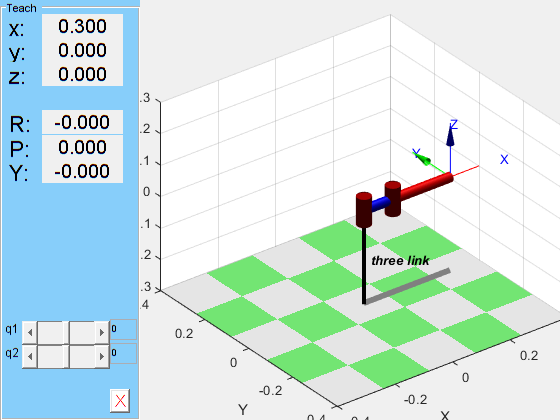

%twolink.plot([0 0])
r.teach


TE = r.fkine( [q(1) q(2)] )

$$\left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \frac{\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{10}\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \frac{\sin\left(q_{1}+q_{2}\right)}{5}+\frac{\sin\left(q_{1}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

q_0 = [pi/2 pi/2]

q_0 =     1.5708    1.5708


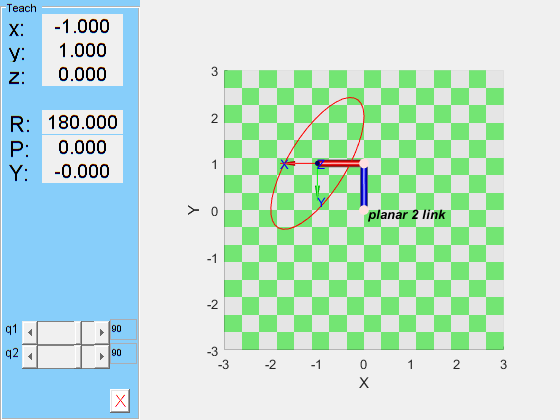

%r.vellipse(q, 'deg');

p2.teach(q_0,'callback', @(r,q) r.vellipse(q), 'view', 'top','workspace',[-3,3,-3,3,-2,1])

b) Suppose that the robot motion is controlled by the kinematic control law


$$\dot{q} = J^{-1}(q)[\dot p_d + K_d(p_d - f(q))]$$


with $K = 10 * I_{2 \times 2}$

%Literal b
%compute the formula above
tb = 1.8;

%This configuration of q draws an L-shape
qb = [-pi/2, pi/2]; %q for b literal


Jb = subs(J3,q(1:2),qb)

$$Jb = \left(\begin{array}{cc} \frac{1}{10} & 0\\ \frac{1}{5} & \frac{1}{5} \end{array}\right)$$

det(Jb) %Not singular

$$ans = \frac{1}{50}$$


vtb = subs(vt,t,tb)

$$vtb = \left(\begin{array}{c} 0\\ -\frac{\pi }{4} \end{array}\right)$$

Kp = 10*eye(2,2)

Kp =     10     0
     0    10


pdb = subs(pd,t,tb)

$$pdb = \left(\begin{array}{c} \frac{1}{10}\\ 0 \end{array}\right)$$


f = T3(1:2,4); %Current position in FK
fb = subs(f,q(1:2),qb)

$$fb = \left(\begin{array}{c} \frac{1}{5}\\ -\frac{1}{10} \end{array}\right)$$


qdotb = inv(Jb)*(vtb+Kp*(pdb - fb)) %rad/sec

$$qdotb = \left(\begin{array}{c} -10\\ 15-\frac{5\,\pi }{4} \end{array}\right)$$


%Where is the end-effector velocity vector pointing to?
%The instantaneous cartesian velocity associated to last result is
vb = eval(Jb*qdotb)

vb =    -1.0000
    0.2146


%Literal c
subs(pd,t,0.2)

$$ans = \left(\begin{array}{c} \frac{1}{10}\\ 0 \end{array}\right)$$